# Lab - Initial value problems 1 - Runge-Kutta methods

**Topics: **Euler, Heun, midpoint method

## IVP setup

clear, clc, format compact

Problem adapted from [https://www.simiode.org/resources/4324/download/2015-Endale-ApplicationsOfODEsToRealWorldSystems.pdf](https://www.simiode.org/resources/4324/download/2015-Endale-ApplicationsOfODEsToRealWorldSystems.pdf)

When a chicken is removed from an oven, its temperature is measured at 300 degrees F.  It is now sitting in a room that is 70 degrees F.

The change in temperature over time can be represented using Newton's law of cooling: $\frac{\textrm{dTemp}}{\textrm{dTime}}=k\left(\textrm{Temp}-{\textrm{Temp}}_{\textrm{Ambient}} \right)$ where k is a constant of proportionality which I've already calculated to be $k=\frac{1}{3}\ln \left(\frac{13}{23}\right)$

What will the temperature of the chicken be at 3 and 6 minutes?

clear, clc

% Place holders so plotting works before code written
time_vals = 0;
Temp_Euler = 0;
Temp_Heun  = 0;
Temp_Mid = 0;

% constant of proportionality
k = 1/3*log(13/23);

% Ambient temperature [deg F]
tAmb = 70;

% differential equation
dTempdTime = @(time,temp) k*(temp-tAmb);

% initial time [in minutes]
time0 = 0;

% final time [in minutes]
timef = 6;

% step size [in minutes]
h = 3;

% initial temp [in degrees Fahrenheit]
temp0 = 300;

% vector for all time values needed
time_vals = time0:h:timef;


## Analytical solution

syms Temp(time)
% set up symbolic differential equation
ode = diff(Temp,time) == k*(Temp - tAmb);
% set up initial condition
cond = Temp(time0) == temp0;

% solve initial value problem
TempExact(time) = dsolve(ode,cond)

$$TempExact(time) = 230\,{\mathrm{e}}^{-\frac{6852014965314385\,\text{time}}{36028797018963968}}+70$$

## Euler's method


$$y_{i+1} =y_i +f\left(t_i ,y_i \right)h$$


Temp_Euler = zeros(size(time_vals));
Temp_Euler(1) = temp0;

phi = dTempdTime(time_vals(1),Temp_Euler(1))

phi = -43.7418

Temp_Euler(2) = Temp_Euler(1) + phi*h;
phi = dTempdTime(time_vals(2),Temp_Euler(2));
Temp_Euler(3) = Temp_Euler(2) + phi*h

Temp_Euler =   300.0000  168.7747  112.4193


## Heun's method


$$y_{i+1} =y_i +\frac{f\left(t_i ,y_i \right)+f\left(t_{i+1} ,y_{i+1}^0 \right)}{2}h$$


Temp_Heun = zeros(size(time_vals));
Temp_Heun(1) = temp0;

slope1 = dTempdTime(time_vals(1),Temp_Heun(1));
temp_naught = Temp_Heun(1) + slope1*h;

slope2 = dTempdTime(time_vals(2), temp_naught);
phi = (slope1+slope2)/2;
Temp_Heun(2) = Temp_Heun(1) + phi*h;
slope1 = dTempdTime(time_vals(2),Temp_Heun(2));
temp_naught = Temp_Heun(2) + slope1*h;

slope2 = dTempdTime(time_vals(3), temp_naught);
phi = (slope1+slope2)/2;
Temp_Heun(3) = Temp_Heun(2) + phi*h

Temp_Heun =   300.0000  206.2096  150.6655


## Midpoint method


$$y_{i+1} =y_i +f\left(t_{i+\frac{1}{2}} ,y_{i+\frac{1}{2}} \right)h$$


Temp_Mid = zeros(size(time_vals));
Temp_Mid = temp0;

slope = dTempdTime(time_vals(1),Temp_Mid(1));
midpoint = Temp_Mid(1) + slope * h/2;

phi = dTempdTime(time_vals(1)+h/2, midpoint);
Temp_Mid(2) = Temp_Mid(1) + phi*h;

slope = dTempdTime(time_vals(2),Temp_Mid(2));
midpoint = Temp_Mid(2) + slope * h/2;

phi = dTempdTime(time_vals(2)+h/2, midpoint);
Temp_Mid(3) = Temp_Mid(2) + phi*h

Temp_Mid =   300.0000  206.2096  150.6655


## Comparing results

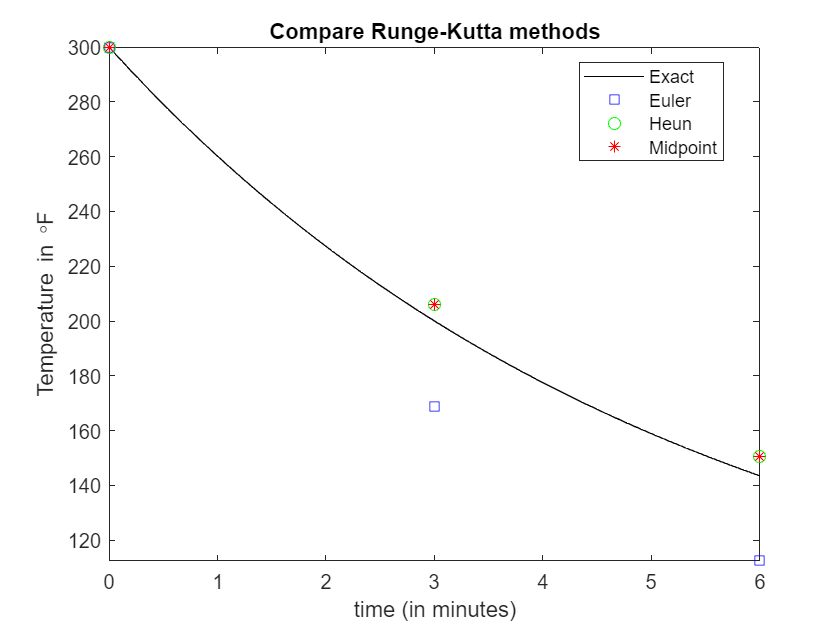

% plot exact
fplot(TempExact, [time0 timef], 'k')
% plot everything else
hold on
plot(time_vals, Temp_Euler, 'bs', time_vals, Temp_Heun, 'go',time_vals, Temp_Mid, 'r*')
hold off
xlabel 'time (in minutes)'
ylabel 'Temperature in \circF'
title 'Compare Runge-Kutta methods'
legend('Exact', 'Euler', 'Heun','Midpoint', 'location','best')


% data table
MPRTE = @(est, true) abs((true-est)/true)*100;
headings = ["t", "Exact", "Euler", "MPRTE-E", "Heun", "MPRTE-H", ...
        "Midpoint", "MPRTE-M"];

for line = 1:length(time_vals)
    if line == 1
        fprintf('%3s %8s %8s %8s %8s %8s %8s %8s\n', headings)
        fprintf('--- -------- -------- -------- -------- -------- -------- --------\n')
    end

    exact = 0;
    fprintf('%3d %8.4f %8.4f %7.2f%% %8.4f %7.2f%% %8.4f %7.2f%%\n', ...
        time_vals(line), exact, Temp_Euler(line), MPRTE(Temp_Euler(line), exact), ...
               Temp_Heun(line), MPRTE(Temp_Heun(line),exact), ...
               Temp_Mid(line), MPRTE(Temp_Mid(line), exact))
end

  t    Exact    Euler  MPRTE-E     Heun  MPRTE-H Midpoint  MPRTE-M


--- -------- -------- -------- -------- -------- -------- --------


  0   0.0000 300.0000     Inf% 300.0000     Inf% 300.0000     Inf%
  3   0.0000 168.7747     Inf% 206.2096     Inf% 206.2096     Inf%
  6   0.0000 112.4193     Inf% 150.6655     Inf% 150.6655     Inf%
